# This is the live script for ESE 6190 HW4 MPC Theory I Ex 2

clear all
clc
%% Basic Deifinition, run this block first
% Define system matrixcs:
A = [1, 1; 0, 1];
% Define input matrixcs:
B = [0; 1];
% sampling time
Ts = 1;
T_sim = 5;
% Horizon Length
N = 5;
% Define weight matrices:
Q = eye(2);
R = 0.1;
P_N = eye(2);
% state and input constraints
n = size(A, 1);
m = size(B, 2);
umin = -1;
umax = 1;
xmin = [-15;-15];
xmax = [15;15];

## 2.1 100 randomly sampled initial condition and corresponding control input

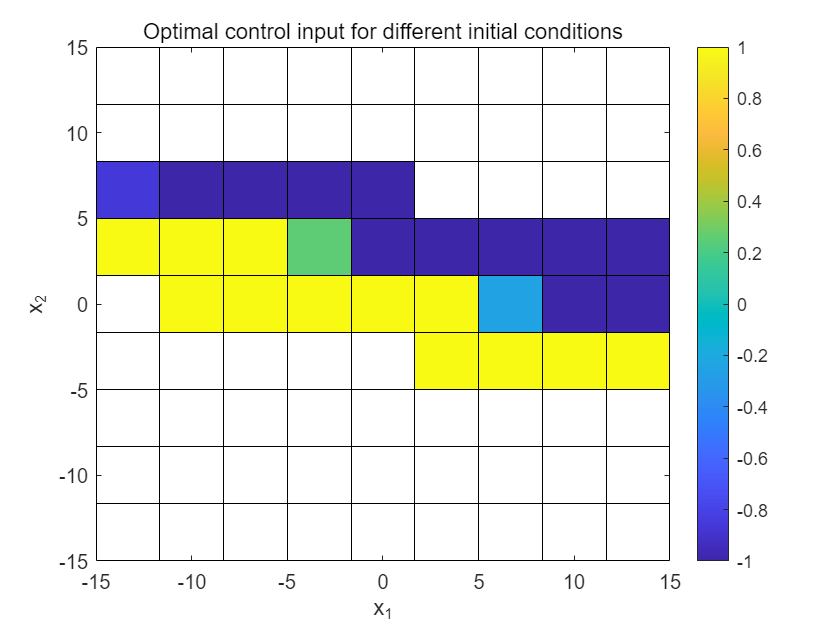

% Also plot the 100*100 result for better illustration
% The input would be set to inf if the CFTOC problem is infeasible
x1 = linspace(-15,15,10);
x2 = linspace(-15,15,10);
U0_record = zeros(10,10);
for j = 1:length(x1)
    for i = 1: length(x2)
        x0 = [x1(j);x2(i)];
        u = CFTOC(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,x0);
        if isnan(u)
            U0_record(i,j) = nan;
        else
            u0 = u(1:m);
            U0_record(i,j) = u0;
        end
    end
end
[X1,X2] = meshgrid(x1,x2);
pcolor(X1,X2,U0_record);
xlabel('x_1')
ylabel('x_2')
title('Optimal control input for different initial conditions')
colorbar

## MPT Toolbox verification for Ex 1.10

% % uncomment this block if needed
% U0_record_ver = zeros(10,10);
% system basics
% warning off
% prediction_model = LTISystem('A', [1, 1; 0, 1], 'B', [0; 1]);
% prediction_model.x.min = [-15;-15];
% prediction_model.x.max = [15;15];
% prediction_model.u.min = -1;
% prediction_model.u.max = 1;
% prediction_model.x.penalty = QuadFunction([1 0; 0 1]);
% prediction_model.u.penalty = QuadFunction(0.1);
% prediction_model.x.with('terminalPenalty');
% simulation_model = LTISystem('A', [1, 1; 0, 1], 'B', [0; 1]);
% PN = QuadFunction([1 0; 0 1]);
% prediction_model.x.terminalPenalty = PN;
% N = 5;
% mpc = MPCController(prediction_model, N);
% loop = ClosedLoop(mpc, simulation_model);
% Nsim = 5;
% for j = 1:length(x1)
%     for i = 1: length(x2)
%         x0 = [x1(j);x2(i)];
%         data = loop.simulate(x0, Nsim);
%         if isempty(data.U)
%             U0_record_ver(i,j) = nan;
%         else
%             u0 = data.U(1:m);
%             U0_record_ver(i,j) = u0;
%         end
%     end
% end
% [X1,X2] = meshgrid(x1,x2);
% pcolor(X1,X2,U0_record_ver);
% title('MPT toolbox verification')
% colorbar

## 2.2 report the result for two different initial conditions.

x0 = [1;1];
u1 = CFTOC(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,x0)

u1 =    -1.0000
   -1.0000
    0.4032
    0.3856
    0.1921


x0 = [-1;-1];
u2 = CFTOC(A,B,Q,R,P_N,N,umin,umax,xmin,xmax,x0)

u2 =     1.0000
    1.0000
   -0.4032
   -0.3856
   -0.1921


function u = CFTOC(A,B,Q,R,P,N,umin,umax,xmin,xmax,x0)
%% This is the function used to solve the CFTOC problem, it is actually the same as mympc in Ex1
    %% linear quadratic optimal control via recursive approach
    %% The method is batch-approach based with substitution, i.e. shooting
    %% essentially, it is solving multiparametric QP about initial state x0
    %% input:
    %  A: system matrix; B: Input matrix; N: control horizon;
    %  Q,R: weight matrices for states and inputs, respectively;
    %  P: terminal cost weight matrix;
    %  umin,umax: box constraints for control inputs, vectors
    %  xmin,xmax: box constraints for state inputs, vectors
    %  x: the initial state
    %% output:
    %  u: the mpc control sequence u = [u0; u1; ...; uN-1];

    % first, rollout the dynamics to get Sx(mathcalA) and Su(mathcalB):
    n = size(A, 1);
    m = size(B, 2);
    Sx = zeros((N+1)*n, n);
    Su = zeros((N+1)*n, N*m);
    for i = 0:N
        Sx(i*n+1:(i+1)*n, 1:n) = A^i;
        for j = 0:N-1
            Su(i*n+1:(i+1)*n, j*m+1:(j+1)*m) = (i-j-1>=0)*A^(i-j-1)*B;
        end
    end

    % Then, get the stack-up weight matrices and rearrage as quadratic form
    % Q_bar(mathcal Q) and R_bar(mathcal R)
    I_N = eye(N);
    Q_bar = kron(I_N, Q);
    Q_bar(end+1:end+n, end+1:end+n) = P;
    R_bar = kron(I_N, R);
    H = 2*(Su'*Q_bar*Su + R_bar);
    F = 2*Sx'*Q_bar*Su;
    Y = x0'*Sx'*Q_bar*Sx*x0;
    
    % add state and input constraints, write them in inequality form
    % here write input constraints also in the stack-up inequality
    % infact, can use quadprog's lb and ub to set the input constraints 
    % since decision variable is u
    % x in (xmin, xmax), u in (umin, umax), xf in (xmin, xmax)
    Ax = [eye(n); -eye(n)];
    Au = [eye(m); -eye(m)];
    Af = [eye(n); -eye(n)];

    % constrauct G block by block
    G_u_block = kron(I_N,Au);
    % here 2 because we have 2 states and need to set upper and lower limit for each state
    % for more general case, consider using num_con_x = size(Ax,1)/n
    % i.e. num_con_x = 2 here
    G_x_block = zeros(N*n*2, N*m);
    for i = 0:N-1
        for j = 0:N-1
            G_x_block(i*2*n+1:(i+1)*2*n, j*m+1:(j+1)*m) = (i-j-1>=0)*Ax*A^(i-j-1)*B;
        end
    end
    % same as above, 2 means upper limit and lower limit for final state
    G_xf_block = zeros(n*2, N*m);
    for j = 0:N-1
        G_xf_block(:, j*m+1:(j+1)*m) = (N-j-1>=0)*Af*A^(N-j-1)*B;
    end
    G = [G_u_block; G_x_block; G_xf_block];

    % construct E block by block
    E_u_block = zeros(2*N, n);
    E_x_block = zeros(N*n*2, n);
    for i = 0:N-1
        E_x_block(i*n*2+1:(i+1)*n*2, 1:n) = -Ax*A^i;
    end
    E_xf_block = -Af*A^N;
    E = [E_u_block;E_x_block;E_xf_block];

    % construct w block by block
    bu = [umax;-umin];
    bx = [xmax;-xmin];
    bf = [xmax;-xmin];
    w_u_block = kron(ones(N,1),bu);
    w_x_block = kron(ones(N,1),bx);
    w = [w_u_block;w_x_block;bf];

    % Get the MPC control input from solving the QP
    options = optimoptions('quadprog','Display','off');
    u = quadprog((H+H')/2, F'*x0, G, w+E*x0,[],[],[],[],[],options);

    if isempty(u)
        u = nan;
    end
end
